# Actividad 7.1: Waypoints

**Paola Rojas Domínguez A01737136**

## Inicialización

Se inicia limpiando la consola y la memoria para evitar conflictos de datos anteriores.

clear all
close all
clc

## Define Vehicle

R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

## Primer conjunto

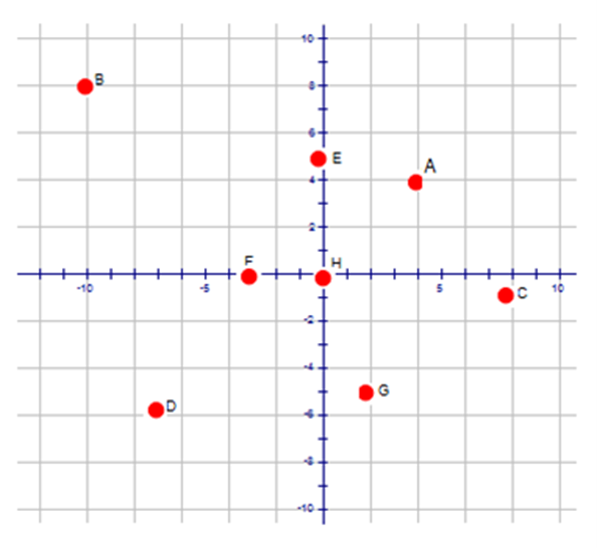

### Parámetros de simulación

Se establecen los parámetros temporales para la simulación: tiempo de muestreo (`sampleTime`) y vector de tiempo (`tVec`). Además, se define la pose inicial del robot (posición `x`, `y` y orientación `θ`), y se inicializa la matriz `pose` que almacenará la trayectoria completa del robot.

sampleTime = 0.1;            
tVec = 0:sampleTime:82;

initPose = [4;4;0];             
pose = zeros(3,numel(tVec));
pose(:,1) = initPose;

### Definición de los waypoints

Se definen los puntos objetivo que el robot debe seguir durante su navegación en el plano. Cada fila del arreglo representa una coordenada `[x, y]`.

waypoints = [4,4; -10,8; -1,8; -5,-7; 0,5; -3,0; 2,-5; 0,0];

### Visualización 2D

Se crea un visualizador en 2D (`Visualizer2D`) para representar el movimiento del robot durante la simulación. Se activa la opción para mostrar los waypoints como referencia.

viz = Visualizer2D;
viz.hasWaypoints = true;

### Pure Pursuit Controller

Se configura un controlador de navegación tipo Pure Pursuit, que permite al robot seguir la trayectoria definida por los waypoints. Se ajustan los parámetros clave como la distancia de anticipación al siguiente punto, la velocidad lineal deseada y la velocidad angular máxima permitida.

controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.35;
controller.DesiredLinearVelocity = 1;
controller.MaxAngularVelocity = 1.5;

### Bucle principal de simulación

Se inicia el bucle de simulación. En cada iteración se realiza lo siguiente:

close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 

### **a) Salidas del controlador y velocidades de ruedas**

Se obtienen las velocidades lineal (`vRef`) y angular (`wRef`) del controlador, y luego se convierten a velocidades individuales de las ruedas (`wL`, `wR`) mediante cinemática inversa.

    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);

### **b) Cinemática directa y velocidades en el mundo**

Se calculan las velocidades reales del cuerpo (`velB`) y se transforman del marco del robot al marco del mundo (`vel`) para actualizar la pose correctamente.

    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world

### **c) Integración de la pose**

Se actualiza la posición y orientación del robot usando integración numérica hacia adelante (método de Euler).

    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 

### **d) Visualización del movimiento**

Se actualiza la escena visual con la nueva pose del robot y se sincroniza con el tiempo real simulado.

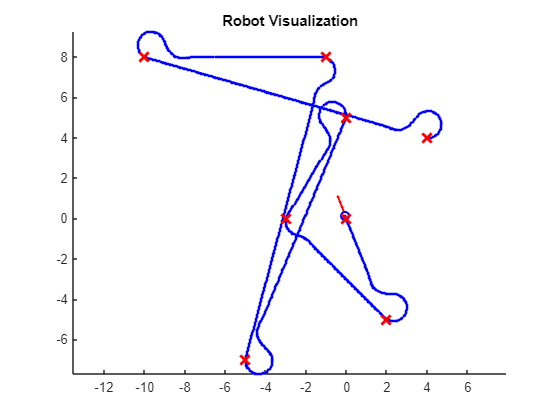

    viz(pose(:,idx),waypoints)
    waitfor(r);
    
end

## Segundo conjunto

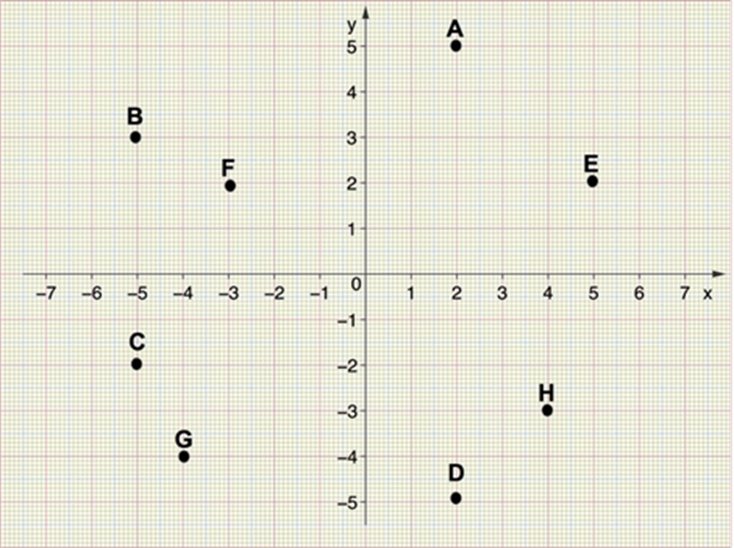

### Parámetros de simulación

Se establecen los parámetros temporales para la simulación: tiempo de muestreo (`sampleTime`) y vector de tiempo (`tVec`). Además, se define la pose inicial del robot (posición `x`, `y` y orientación `θ`), y se inicializa la matriz `pose` que almacenará la trayectoria completa del robot.

sampleTime = 0.1;            
tVec = 0:sampleTime:54;

initPose = [2;5;0];             
pose = zeros(3,numel(tVec));
pose(:,1) = initPose;

### Definición de los waypoints

Se definen los puntos objetivo que el robot debe seguir durante su navegación en el plano. Cada fila del arreglo representa una coordenada `[x, y]`.

waypoints = [2,5; -5,3; -5,-2; -2,-5; 5,2; -3,2; -4,-4; 4,-3];

### Visualización 2D

Se crea un visualizador en 2D (`Visualizer2D`) para representar el movimiento del robot durante la simulación. Se activa la opción para mostrar los waypoints como referencia.

viz = Visualizer2D;
viz.hasWaypoints = true;

### Pure Pursuit Controller

Se configura un controlador de navegación tipo Pure Pursuit, que permite al robot seguir la trayectoria definida por los waypoints. Se ajustan los parámetros clave como la distancia de anticipación al siguiente punto, la velocidad lineal deseada y la velocidad angular máxima permitida.

controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.35;
controller.DesiredLinearVelocity = 1;
controller.MaxAngularVelocity = 1.5;

### Bucle principal de simulación

Se inicia el bucle de simulación. En cada iteración se realiza lo siguiente:

close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 

#### **a) Salidas del controlador y velocidades de ruedas**

Se obtienen las velocidades lineal (`vRef`) y angular (`wRef`) del controlador, y luego se convierten a velocidades individuales de las ruedas (`wL`, `wR`) mediante cinemática inversa.

    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);

#### **b) Cinemática directa y velocidades en el mundo**

Se calculan las velocidades reales del cuerpo (`velB`) y se transforman del marco del robot al marco del mundo (`vel`) para actualizar la pose correctamente.

    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world

#### **c) Integración de la pose**

Se actualiza la posición y orientación del robot usando integración numérica hacia adelante (método de Euler).

    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 

#### **d) Visualización del movimiento**

Se actualiza la escena visual con la nueva pose del robot y se sincroniza con el tiempo real simulado.

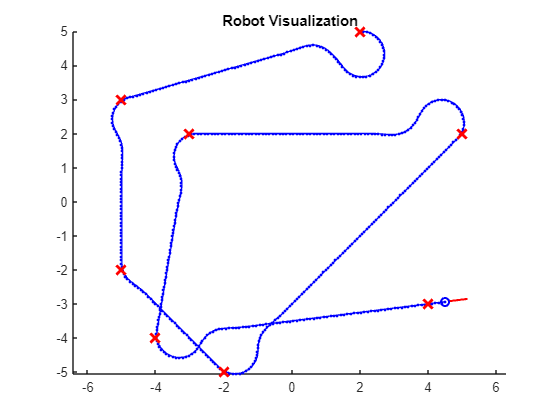

    viz(pose(:,idx),waypoints)
    waitfor(r);
    
end

## Tercer conjunto

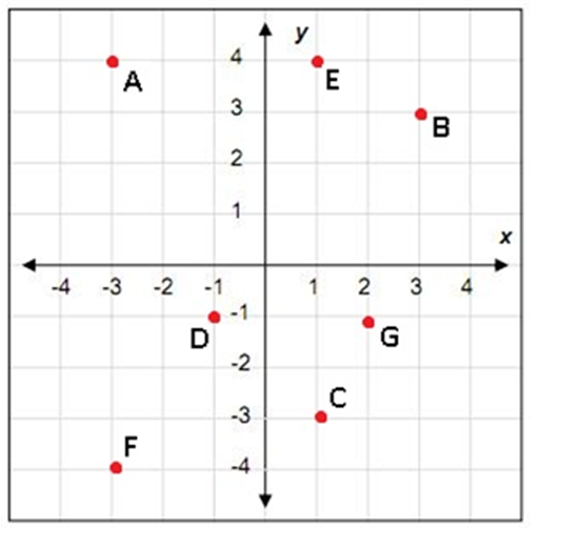

### Parámetros de simulación

Se establecen los parámetros temporales para la simulación: tiempo de muestreo (`sampleTime`) y vector de tiempo (`tVec`). Además, se define la pose inicial del robot (posición `x`, `y` y orientación `θ`), y se inicializa la matriz `pose` que almacenará la trayectoria completa del robot.

sampleTime = 0.1;            
tVec = 0:sampleTime:51;

initPose = [-3;4;0];             
pose = zeros(3,numel(tVec));
pose(:,1) = initPose;

### Definición de los waypoints

Se definen los puntos objetivo que el robot debe seguir durante su navegación en el plano. Cada fila del arreglo representa una coordenada `[x, y]`.

waypoints = [-3,4; 3,3; 1,-3; -1,-1; 1,4; -3,-4; 2,-1];

### Visualización 2D

Se crea un visualizador en 2D (`Visualizer2D`) para representar el movimiento del robot durante la simulación. Se activa la opción para mostrar los waypoints como referencia.

viz = Visualizer2D;
viz.hasWaypoints = true;

### Pure Pursuit Controller

Se configura un controlador de navegación tipo Pure Pursuit, que permite al robot seguir la trayectoria definida por los waypoints. Se ajustan los parámetros clave como la distancia de anticipación al siguiente punto, la velocidad lineal deseada y la velocidad angular máxima permitida.

controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.35;
controller.DesiredLinearVelocity = 1;
controller.MaxAngularVelocity = 1.5;

### Bucle principal de simulación

Se inicia el bucle de simulación. En cada iteración se realiza lo siguiente:

close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 

#### **a) Salidas del controlador y velocidades de ruedas**

Se obtienen las velocidades lineal (`vRef`) y angular (`wRef`) del controlador, y luego se convierten a velocidades individuales de las ruedas (`wL`, `wR`) mediante cinemática inversa.

    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);

#### **b) Cinemática directa y velocidades en el mundo**

Se calculan las velocidades reales del cuerpo (`velB`) y se transforman del marco del robot al marco del mundo (`vel`) para actualizar la pose correctamente.

    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world

#### **c) Integración de la pose**

Se actualiza la posición y orientación del robot usando integración numérica hacia adelante (método de Euler).

    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 

#### **d) Visualización del movimiento**

Se actualiza la escena visual con la nueva pose del robot y se sincroniza con el tiempo real simulado.

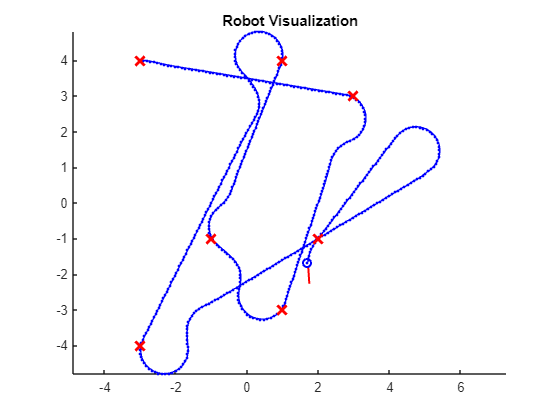

    viz(pose(:,idx),waypoints)
    waitfor(r);
    
end

## Perro

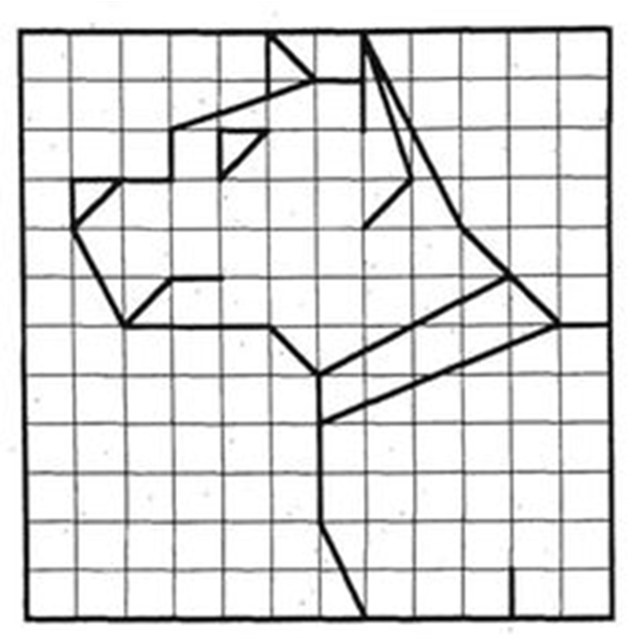

### Parámetros de simulación

Se establecen los parámetros temporales para la simulación: tiempo de muestreo (`sampleTime`) y vector de tiempo (`tVec`). Además, se define la pose inicial del robot (posición `x`, `y` y orientación `θ`), y se inicializa la matriz `pose` que almacenará la trayectoria completa del robot.

sampleTime = 0.1;            
tVec = 0:sampleTime:83;

initPose = [10;1;0];             
pose = zeros(3,numel(tVec));
pose(:,1) = initPose;

### Definición de los waypoints

Se definen los puntos objetivo que el robot debe seguir durante su navegación en el plano. Cada fila del arreglo representa una coordenada `[x, y]`.

waypoints = [10,1; 10,0; 12,0; 12,6; 11,6; 9,8; 7,12; 8,9; 7,8; 7,11; 6,11; 5,12; 5,10.5; 3,10; 5,10; 4,9; 4,10; 3,10; 3,9; 2,9; 1,9; 1,8; 2,9; 1,9; 2,6; 3,7; 4,7; 3,7; 2,6; 5,6; 6,5; 10,7; 11,6; 6,4; 6,5; 6,2; 7,0; 10,0];

### Visualización 2D

Se crea un visualizador en 2D (`Visualizer2D`) para representar el movimiento del robot durante la simulación. Se activa la opción para mostrar los waypoints como referencia.

viz = Visualizer2D;
viz.hasWaypoints = true;

### Pure Pursuit Controller

Se configura un controlador de navegación tipo Pure Pursuit, que permite al robot seguir la trayectoria definida por los waypoints. Se ajustan los parámetros clave como la distancia de anticipación al siguiente punto, la velocidad lineal deseada y la velocidad angular máxima permitida.

controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.35;
controller.DesiredLinearVelocity = 1;
controller.MaxAngularVelocity = 3.5;

### Bucle principal de simulación

Se inicia el bucle de simulación. En cada iteración se realiza lo siguiente:

close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 

#### **a) Salidas del controlador y velocidades de ruedas**

Se obtienen las velocidades lineal (`vRef`) y angular (`wRef`) del controlador, y luego se convierten a velocidades individuales de las ruedas (`wL`, `wR`) mediante cinemática inversa.

    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);

#### **b) Cinemática directa y velocidades en el mundo**

Se calculan las velocidades reales del cuerpo (`velB`) y se transforman del marco del robot al marco del mundo (`vel`) para actualizar la pose correctamente.

    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world

#### **c) Integración de la pose**

Se actualiza la posición y orientación del robot usando integración numérica hacia adelante (método de Euler).

    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 

#### **d) Visualización del movimiento**

Se actualiza la escena visual con la nueva pose del robot y se sincroniza con el tiempo real simulado.

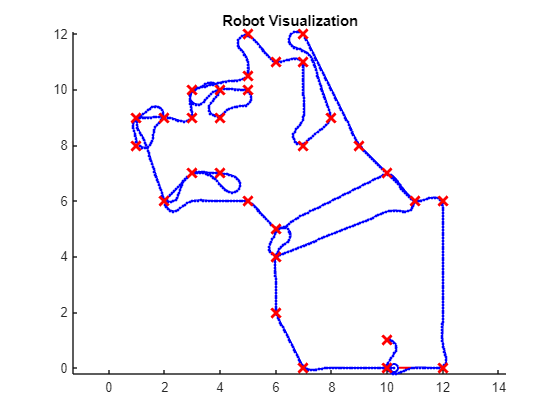

    viz(pose(:,idx),waypoints)
    waitfor(r);
    
end

## Flor

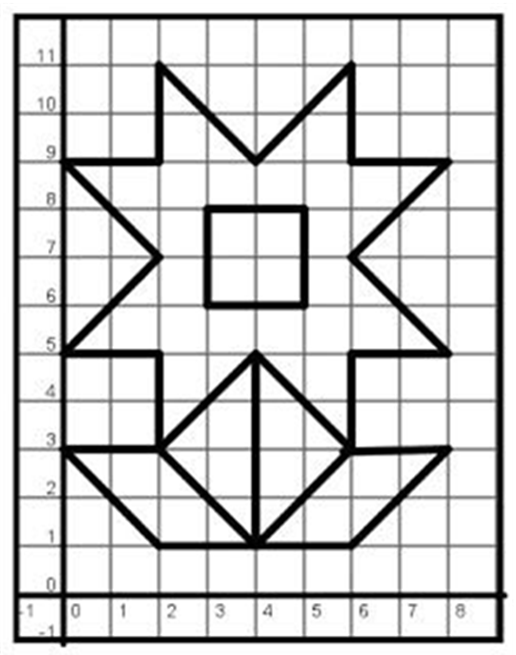

### Parámetros de simulación

Se establecen los parámetros temporales para la simulación: tiempo de muestreo (`sampleTime`) y vector de tiempo (`tVec`). Además, se define la pose inicial del robot (posición `x`, `y` y orientación `θ`), y se inicializa la matriz `pose` que almacenará la trayectoria completa del robot.

sampleTime = 0.1;            
tVec = 0:sampleTime:75;

initPose = [4;1;0];             
pose = zeros(3,numel(tVec));
pose(:,1) = initPose;

### Definición de los waypoints

Se definen los puntos objetivo que el robot debe seguir durante su navegación en el plano. Cada fila del arreglo representa una coordenada `[x, y]`.

waypoints = [4,1; 6,1; 8,3; 6,3; 4,1; 2,3; 0,3; 2,1; 4,1; 4,5; 2,3; 2,5; 0,5; 2,7; 0,9; 2,9; 2,11; 4,9; 6,11; 6,9; 8,9; 6,7; 8,5; 6,5; 6,3; 4,5; 4,6; 3,6; 3,8; 5,8; 5,6; 4,6; 4,5];

### Visualización 2D

Se crea un visualizador en 2D (`Visualizer2D`) para representar el movimiento del robot durante la simulación. Se activa la opción para mostrar los waypoints como referencia.

viz = Visualizer2D;
viz.hasWaypoints = true;

### Pure Pursuit Controller

Se configura un controlador de navegación tipo Pure Pursuit, que permite al robot seguir la trayectoria definida por los waypoints. Se ajustan los parámetros clave como la distancia de anticipación al siguiente punto, la velocidad lineal deseada y la velocidad angular máxima permitida.

controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.35;
controller.DesiredLinearVelocity = 1;
controller.MaxAngularVelocity = 3.5;

### Bucle principal de simulación

Se inicia el bucle de simulación. En cada iteración se realiza lo siguiente:

close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 

#### **a) Salidas del controlador y velocidades de ruedas**

Se obtienen las velocidades lineal (`vRef`) y angular (`wRef`) del controlador, y luego se convierten a velocidades individuales de las ruedas (`wL`, `wR`) mediante cinemática inversa.

    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);

#### **b) Cinemática directa y velocidades en el mundo**

Se calculan las velocidades reales del cuerpo (`velB`) y se transforman del marco del robot al marco del mundo (`vel`) para actualizar la pose correctamente.

    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world

#### **c) Integración de la pose**

Se actualiza la posición y orientación del robot usando integración numérica hacia adelante (método de Euler).

    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 

#### **d) Visualización del movimiento**

Se actualiza la escena visual con la nueva pose del robot y se sincroniza con el tiempo real simulado.

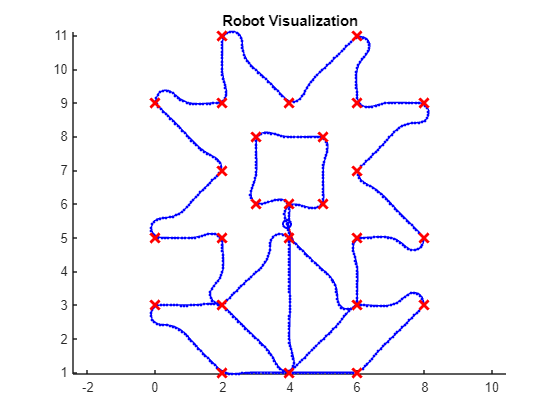

    viz(pose(:,idx),waypoints)
    waitfor(r);
    
end

## Durazno

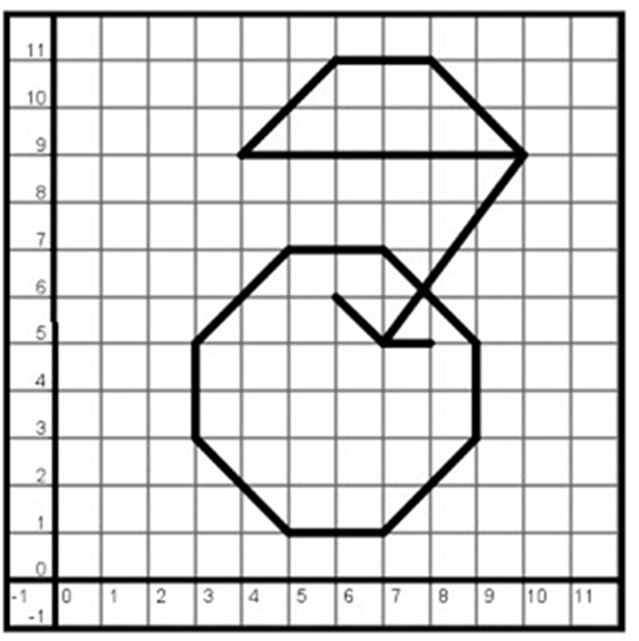

### Parámetros de simulación

Se establecen los parámetros temporales para la simulación: tiempo de muestreo (`sampleTime`) y vector de tiempo (`tVec`). Además, se define la pose inicial del robot (posición `x`, `y` y orientación `θ`), y se inicializa la matriz `pose` que almacenará la trayectoria completa del robot.

sampleTime = 0.1;            
tVec = 0:sampleTime:45;

initPose = [10;9;0];             
pose = zeros(3,numel(tVec));
pose(:,1) = initPose;

### Definición de los waypoints

Se definen los puntos objetivo que el robot debe seguir durante su navegación en el plano. Cada fila del arreglo representa una coordenada `[x, y]`.

waypoints = [10,9; 8,11; 6,11; 4,9; 10,9; 7,5; 8,5; 7,5; 5,7; 3,5; 3,3; 5,1; 7,1; 9,3; 9,5; 7,7; 5,7];

### Visualización 2D

Se crea un visualizador en 2D (`Visualizer2D`) para representar el movimiento del robot durante la simulación. Se activa la opción para mostrar los waypoints como referencia.

viz = Visualizer2D;
viz.hasWaypoints = true;

### Pure Pursuit Controller

Se configura un controlador de navegación tipo Pure Pursuit, que permite al robot seguir la trayectoria definida por los waypoints. Se ajustan los parámetros clave como la distancia de anticipación al siguiente punto, la velocidad lineal deseada y la velocidad angular máxima permitida.

controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.35;
controller.DesiredLinearVelocity = 1;
controller.MaxAngularVelocity = 3.5;

### Bucle principal de simulación

Se inicia el bucle de simulación. En cada iteración se realiza lo siguiente:

close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 

#### **a) Salidas del controlador y velocidades de ruedas**

Se obtienen las velocidades lineal (`vRef`) y angular (`wRef`) del controlador, y luego se convierten a velocidades individuales de las ruedas (`wL`, `wR`) mediante cinemática inversa.

    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);

#### **b) Cinemática directa y velocidades en el mundo**

Se calculan las velocidades reales del cuerpo (`velB`) y se transforman del marco del robot al marco del mundo (`vel`) para actualizar la pose correctamente.

    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world

#### **c) Integración de la pose**

Se actualiza la posición y orientación del robot usando integración numérica hacia adelante (método de Euler).

    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 

#### **d) Visualización del movimiento**

Se actualiza la escena visual con la nueva pose del robot y se sincroniza con el tiempo real simulado.

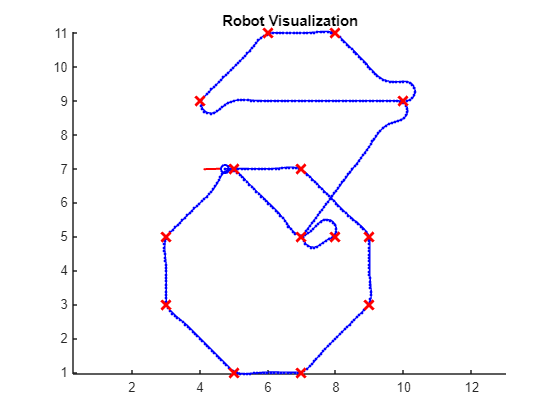

    viz(pose(:,idx),waypoints)
    waitfor(r);
    
end